% Load the training data 
data = load("D:\college\FYP\TrainingData\393i_Multi\393i_multi.mat");
trainingDataMulti = data.trainingDataMulti;


% Create an imageDatastore using the files from the table.
imds = imageDatastore(trainingDataMulti.imageFilename);

% Create a boxLabelDatastore using the label columns from the table.
blds = boxLabelDatastore(trainingDataMulti(:,2:end));

% Combine the datastores.
ds = combine(imds, blds);

preDetector = yolov4ObjectDetector("tiny-yolov4-coco");
preDetector.Network;

% Specify the input size
inputSize = [224 224 3];

trainingDataForEstimation = transform(ds,@(data)preprocessData(data,inputSize));

numAnchors = 6;
[anchors, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);
area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:);anchors(4:6,:)};


% Define all your classes
classes = {'NoParking', 'Parking', 'Stop', 'U_Turn', 'Zebra_Crossing'};

preDetector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);


options = trainingOptions("sgdm", ...
    InitialLearnRate=0.0001, ...
    MiniBatchSize=16,...
    MaxEpochs=100, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    VerboseFrequency=5, ...
    Plots="training-progress");


*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* NoParking
* Parking
* Stop
* U_Turn
* Zebra_Crossing

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      1          5         00:00:44       0.0001         41.322   
      1         10         00:01:04       0.0001         18.006   
      1         15         00:01:23       0.0001         17.524   
      1         20         00:01:42       0.0001         15.689   
      1         25         00:02:01       0.0001         13.38    
      2         30         00:02:21       0.0001         12.579   
      2         35         00:02:39       0.0001         10.808   
      2         40       

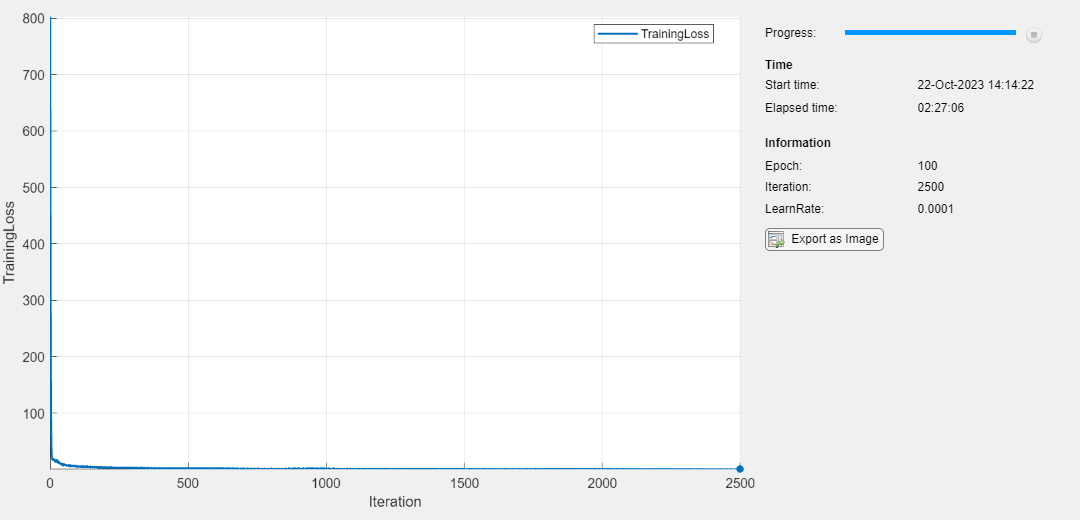

     100       2500        02:26:56       0.0001        0.22212   

*************************************************************************
Detector training complete.
*************************************************************************



% Train the YOLO v4 network.
detector = trainYOLOv4ObjectDetector(ds,preDetector,options);

save('multiLabel_yolov4_393i_100e.mat','detector');


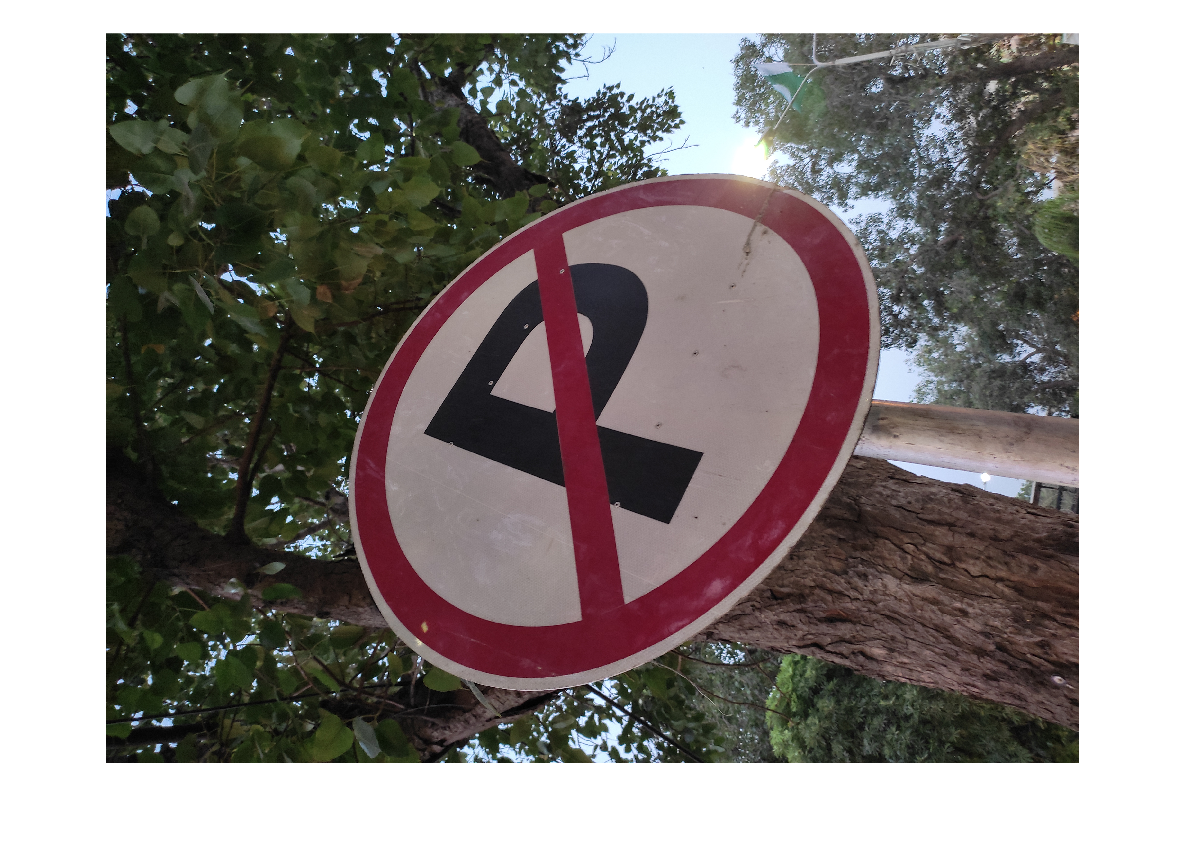

I = imread("D:\college\FYP\Scripts\location\IMG_20230816_185525.jpg");

[bboxes, scores, labels] = detect(detector,I,Threshold=0.05);
detectedImg = insertObjectAnnotation(I,"Rectangle",bboxes,labels,"LineWidth",8,"FontSize",24);
figure
imshow(detectedImg)

function data = preprocessData(data,targetSize)
for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    bboxes = data{num,2};
    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    data(num,1:2) = {I,bboxes};
end
end
